## 1.(d) Forward differencing of $sin(cos(tan(x^2)))$

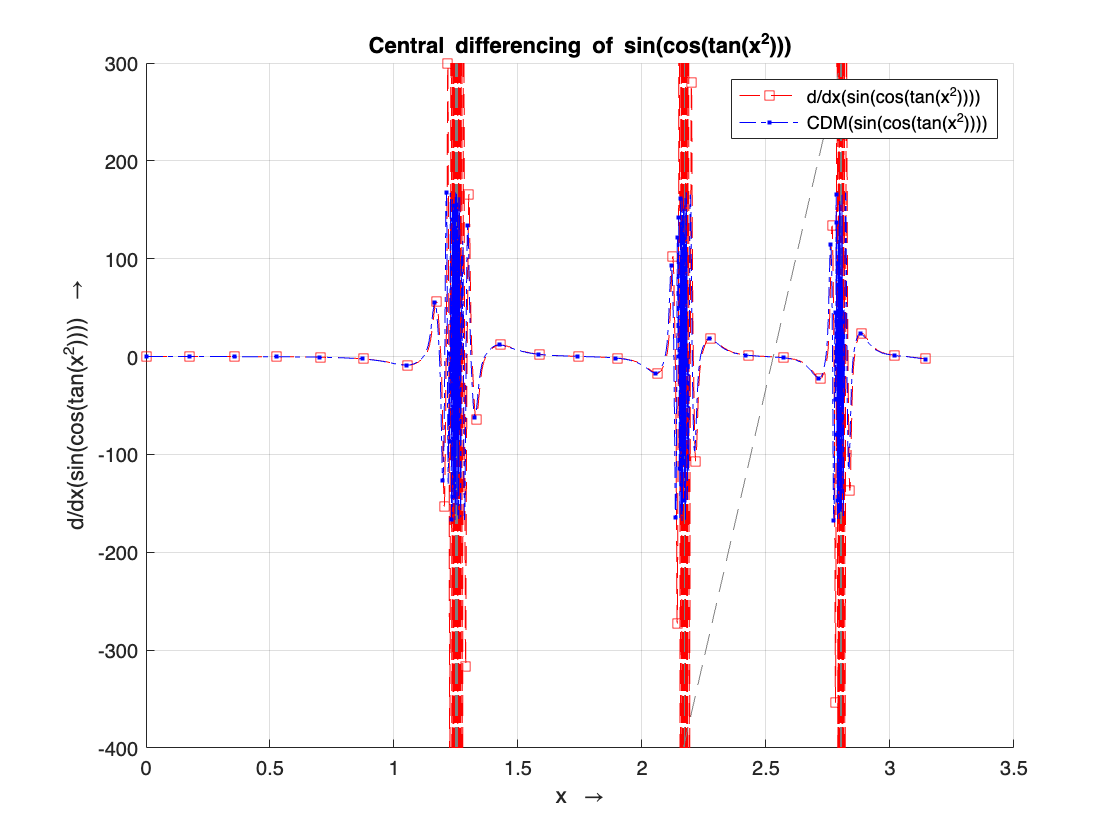

clear ALL;
clc;

syms x h;
fx = sin(cos(tan(x^2)));
diff_fx = diff(fx);
fdm_fx = (subs(fx, x, x + h) - fx) / h;
fdm_to_plot = subs(fdm_fx, h, 0.01); % reduced value of h for better accuracy

figure;
hold ON;
fplot(diff_fx, [0 pi], 'reds--');
fplot(fdm_to_plot, [0 pi], 'blue.-.');
legend("d/dx(sin(cos(tan(x^2))))", "CDM(sin(cos(tan(x^2))))");
title("Central differencing of sin(cos(tan(x^2)))");
xlabel("x \rightarrow");
ylabel("d/dx(sin(cos(tan(x^2)))) \rightarrow");
hold OFF;
grid ON;

### Key takeaways $-$

- Use of **Symbolic Mathematical Toolkit** to symbolically represent functions and derive inferences and operate on them. Using `syms` keyword we can declare symbolic variables. Like `syms x h `declares two symbolic variables `x` and `h`. 

- Use of function `subs` to substitute value of a function argument by another value. Like `subs(fx, x, x + h)` means replace the argument of $f(x)$ from `x` to `x + h`.

- Use of function `fplot` to plot functions. Like `fplot(sin(x), [-2*pi 2*pi])` plots the sine function within the limits $-2\pi$ to $2\pi$.

- Code for Experiment no. 1 can be downloaded from [https://github.com/bhargawananbhuyan/computational-electromagnetics/raw/main/exp1.mlx](https://github.com/bhargawananbhuyan/computational-electromagnetics/raw/main/exp1.mlx)